clear;
load('Data\Indian_pines.mat');
h = HSI(indian_pines);
clear indian_pines;
h.preprocess('std');

endmember_num = 5;
len = h.shape(1) * h.shape(2);
loc_list = randi(len, [endmember_num, 1]);

E = h.locate(loc_list, '1D');
volume = sqrt(det(E * E' / h.shape(end)));

for i = 1:endmember_num
    tmp_list = loc_list;
    for j = 1:len
        tmp_list(i) = j;
        E = h.locate(tmp_list, '1D');
        tmp = sqrt(det(E * E' / h.shape(end)));
        if tmp > volume
            volume = tmp;
            loc_list(i) = j;
        end
    end
end

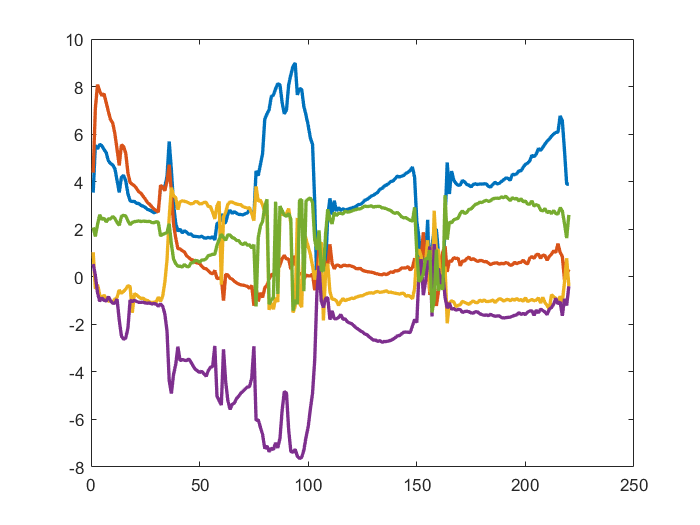

E = h.locate(loc_list, '1D');
plot(E');

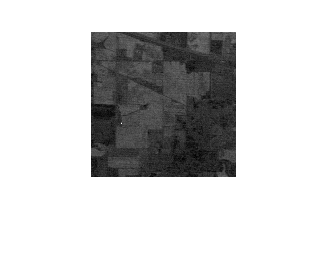

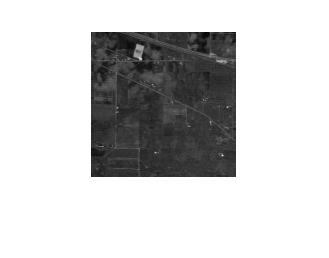

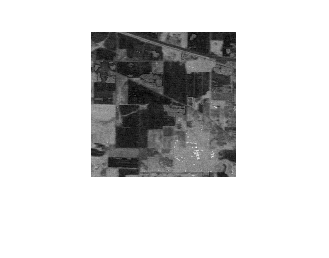

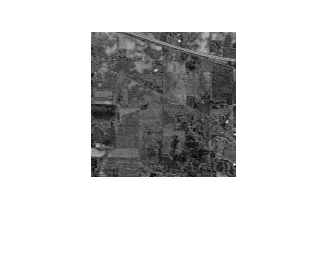

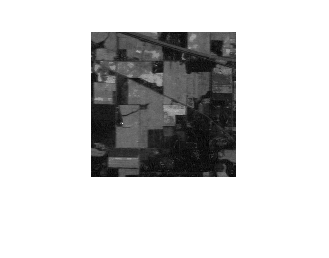

P = pinv(E * E') * E * h.F()';
P = reshape(P', [h.shape(1), h.shape(2), endmember_num]);
for i = 1:endmember_num
    figure, imshow(P(:, :, i), []);
end